addpath('Kinematics')
addpath('Kinetics')

supressed_print= evalc('run Ball_Plate_Kinetics_Newton_Euler.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Decouple the Equations Of Motion, No Linearization

Here, we decouple the system using several simplifying assumptions.

## Substitute in the Decoupling Assumptions

### x and beta Dynamics

#### Ball Kinetics

First, substitute $\gamma = \dot\gamma = 0$ into the ball's $y$ direction moment equation.

NL_Dcpld_SumMBall_x = simplify(subs(SumMBall(2),[gamma gamma_dot gamma_ddot ], [0 0 0]))

$$NL\_Dcpld\_SumMBall\_x = 7\,\ddot{x}+5\,\ddot{\beta }\,z_{b}+2\,\ddot{\beta }\,r_{b}=5\,{\dot{\beta }}^{2}\,x+5\,g\,\sin\left(\beta \right)$$

#### Plate Kinetics

Next, do the kinetics of the plate alone and isolate the $y$ direction moment equation. Make the same assumptions as above and keep the moment due to the normal force, $M_N$, general for now. $M_N$ is defined with respect to the S1 frame. 

NL_Dcpld_SumMPlate_x = subs(SumMPlate(2),[gamma gamma_dot gamma_ddot], [0 0 0])

$$NL\_Dcpld\_SumMPlate\_x = T_{\beta }+g\,m_{b}\,x\,\cos\left(\beta \right)+g\,m_{b}\,z_{b}\,\sin\left(\beta \right)+g\,m_{p}\,z_{p}\,\sin\left(\beta \right)=\ddot{\beta }\,m_{b}\,x^{2}+2\,\dot{\beta }\,m_{b}\,x\,\dot{x}+m_{b}\,\ddot{x}\,z_{b}+0.4000\,m_{b}\,r_{b}\,\ddot{x}+\ddot{\beta }\,m_{b}\,{z_{b}}^{2}+\ddot{\beta }\,m_{p}\,{z_{p}}^{2}+0.4000\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}+I_{p}^{\mathrm{xx}}\,\ddot{\beta }$$

#### Bring Together Nonlinear Decoupled Moment Equations and Solve for Highest Order Terms

NL_Dcpld_EOMS_x = [NL_Dcpld_SumMBall_x;NL_Dcpld_SumMPlate_x];
[NL_Dcpld_CoeffMat_x,NL_Dcpld_ExtTerms_x] = equationsToMatrix(NL_Dcpld_EOMS_x , [x_ddot, beta_ddot]); 
NL_Dcpld_SolvedEOMs_x = stateVec1_dot == [x_dot; [1 0]*(NL_Dcpld_CoeffMat_x\NL_Dcpld_ExtTerms_x); beta_dot;[0 1]*(NL_Dcpld_CoeffMat_x\NL_Dcpld_ExtTerms_x)]

$$NL\_Dcpld\_SolvedEOMs\_x = \left[\begin{array}{c} \dot{x}=\dot{x}\\ \ddot{x}=\frac{5\,{\dot{\beta }}^{2}\,m_{b}\,x^{3}-5\,T_{\beta }\,z_{b}-2\,T_{\beta }\,r_{b}+5\,I_{p}^{\mathrm{xx}}\,{\dot{\beta }}^{2}\,x+5\,I_{p}^{\mathrm{xx}}\,g\,\sin\left(\beta \right)+2\,{\dot{\beta }}^{2}\,m_{b}\,{r_{b}}^{2}\,x+2\,g\,m_{b}\,{r_{b}}^{2}\,\sin\left(\beta \right)+5\,{\dot{\beta }}^{2}\,m_{b}\,x\,{z_{b}}^{2}+5\,{\dot{\beta }}^{2}\,m_{p}\,x\,{z_{p}}^{2}+5\,g\,m_{b}\,x^{2}\,\sin\left(\beta \right)+5\,g\,m_{p}\,{z_{p}}^{2}\,\sin\left(\beta \right)+4\,\dot{\beta }\,m_{b}\,r_{b}\,x\,\dot{x}+10\,\dot{\beta }\,m_{b}\,x\,\dot{x}\,z_{b}-2\,g\,m_{b}\,r_{b}\,x\,\cos\left(\beta \right)-5\,g\,m_{b}\,x\,z_{b}\,\cos\left(\beta \right)-2\,g\,m_{b}\,r_{b}\,z_{b}\,\sin\left(\beta \right)-2\,g\,m_{p}\,r_{b}\,z_{p}\,\sin\left(\beta \right)-5\,g\,m_{p}\,z_{b}\,z_{p}\,\sin\left(\beta \right)}{7\,m_{b}\,x^{2}+2\,m_{b}\,{z_{b}}^{2}-4\,m_{b}\,r_{b}\,z_{b}+7\,m_{p}\,{z_{p}}^{2}+2\,m_{b}\,{r_{b}}^{2}+7\,I_{p}^{\mathrm{xx}}}\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=\frac{7\,T_{\beta }-14\,\dot{\beta }\,m_{b}\,x\,\dot{x}+7\,g\,m_{b}\,x\,\cos\left(\beta \right)-2\,{\dot{\beta }}^{2}\,m_{b}\,r_{b}\,x-2\,g\,m_{b}\,r_{b}\,\sin\left(\beta \right)-5\,{\dot{\beta }}^{2}\,m_{b}\,x\,z_{b}+2\,g\,m_{b}\,z_{b}\,\sin\left(\beta \right)+7\,g\,m_{p}\,z_{p}\,\sin\left(\beta \right)}{7\,m_{b}\,x^{2}+2\,m_{b}\,{z_{b}}^{2}-4\,m_{b}\,r_{b}\,z_{b}+7\,m_{p}\,{z_{p}}^{2}+2\,m_{b}\,{r_{b}}^{2}+7\,I_{p}^{\mathrm{xx}}} \end{array}\right]$$

#### Find Input Matrix $g_x(\tilde{x})$

A system with state vector $\tilde{x}_{1} $:


$$\tilde{x}_{1} = [x ~\dot{x} ~\beta ~\dot{\beta}]^T

$$


And state equation:


$$\dot\tilde{x}_{1} ~=~ f_x(\tilde{x}) + g_x(\tilde{x})T_\beta$$
 

[g_x,g_x_extra_terms] = equationsToMatrix(NL_Dcpld_SolvedEOMs_x , T_beta);
g_x = -g_x

$$g\_x = \left[\begin{array}{c} 0\\ -\frac{5\,z_{b}+2\,r_{b}}{7\,m_{b}\,x^{2}+2\,m_{b}\,{z_{b}}^{2}-4\,m_{b}\,r_{b}\,z_{b}+7\,m_{p}\,{z_{p}}^{2}+2\,m_{b}\,{r_{b}}^{2}+7\,I_{p}^{\mathrm{xx}}}\\ 0\\ \frac{7}{7\,m_{b}\,x^{2}+2\,m_{b}\,{z_{b}}^{2}-4\,m_{b}\,r_{b}\,z_{b}+7\,m_{p}\,{z_{p}}^{2}+2\,m_{b}\,{r_{b}}^{2}+7\,I_{p}^{\mathrm{xx}}} \end{array}\right]$$

g_x_extra_terms = -g_x_extra_terms;

f_x = - g_x_extra_terms + stateVec1_dot

$$f\_x = \left[\begin{array}{c} \dot{x}\\ \frac{5\,{\dot{\beta }}^{2}\,m_{b}\,x^{3}+5\,I_{p}^{\mathrm{xx}}\,{\dot{\beta }}^{2}\,x+5\,I_{p}^{\mathrm{xx}}\,g\,\sin\left(\beta \right)+2\,{\dot{\beta }}^{2}\,m_{b}\,{r_{b}}^{2}\,x+2\,g\,m_{b}\,{r_{b}}^{2}\,\sin\left(\beta \right)+5\,{\dot{\beta }}^{2}\,m_{b}\,x\,{z_{b}}^{2}+5\,{\dot{\beta }}^{2}\,m_{p}\,x\,{z_{p}}^{2}+5\,g\,m_{b}\,x^{2}\,\sin\left(\beta \right)+5\,g\,m_{p}\,{z_{p}}^{2}\,\sin\left(\beta \right)+4\,\dot{\beta }\,m_{b}\,r_{b}\,x\,\dot{x}+10\,\dot{\beta }\,m_{b}\,x\,\dot{x}\,z_{b}-2\,g\,m_{b}\,r_{b}\,x\,\cos\left(\beta \right)-5\,g\,m_{b}\,x\,z_{b}\,\cos\left(\beta \right)-2\,g\,m_{b}\,r_{b}\,z_{b}\,\sin\left(\beta \right)-2\,g\,m_{p}\,r_{b}\,z_{p}\,\sin\left(\beta \right)-5\,g\,m_{p}\,z_{b}\,z_{p}\,\sin\left(\beta \right)}{7\,m_{b}\,x^{2}+2\,m_{b}\,{z_{b}}^{2}-4\,m_{b}\,r_{b}\,z_{b}+7\,m_{p}\,{z_{p}}^{2}+2\,m_{b}\,{r_{b}}^{2}+7\,I_{p}^{\mathrm{xx}}}\\ \dot{\beta }\\ -\frac{14\,\dot{\beta }\,m_{b}\,x\,\dot{x}-7\,g\,m_{b}\,x\,\cos\left(\beta \right)+2\,{\dot{\beta }}^{2}\,m_{b}\,r_{b}\,x+2\,g\,m_{b}\,r_{b}\,\sin\left(\beta \right)+5\,{\dot{\beta }}^{2}\,m_{b}\,x\,z_{b}-2\,g\,m_{b}\,z_{b}\,\sin\left(\beta \right)-7\,g\,m_{p}\,z_{p}\,\sin\left(\beta \right)}{7\,m_{b}\,x^{2}+2\,m_{b}\,{z_{b}}^{2}-4\,m_{b}\,r_{b}\,z_{b}+7\,m_{p}\,{z_{p}}^{2}+2\,m_{b}\,{r_{b}}^{2}+7\,I_{p}^{\mathrm{xx}}} \end{array}\right]$$


simplify(f_x + g_x*T_beta - rhs(NL_Dcpld_SolvedEOMs_x))%check that the EOMs in terms of f_x, g_x, and T_beta are correct

$$ans = \left[\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right]$$

## Best Current Estimates of Numerical System Parameters

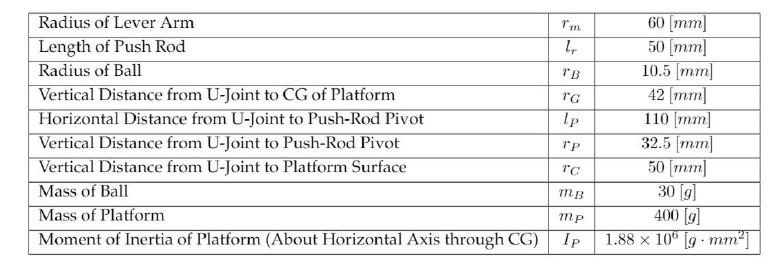

rB = .0105; %[m]
rG = .042; %[m]
rC = .050; %[m]
mB = .030; %[kg]
mP = .400; %[kg]
IP = 1.88e6*(1/1000)*(1/1000)^2; %[kg*m^2]
IB = (2/5)*mB*rB^2;%ball inertia [kg-m^2] 
g_num = 9.81; %[m/s^2]

Num_Params = [rB  rC+rB mB mP IP IB g_num rG];
Sym_Params = [r_b z_b m_b m_p I_p__xx I_b g z_p];

Substituting known numerical parameters and our assumptions into the symbolic equations of motion:

num_NL_Dcpld_SolvedEOMs_x = subs(NL_Dcpld_SolvedEOMs_x, Sym_Params, Num_Params)

$$num\_NL\_Dcpld\_SolvedEOMs\_x = \left[\begin{array}{c} \dot{x}=\dot{x}\\ \ddot{x}=\frac{0.0732\,\sin\left(\beta \right)-0.3235\,T_{\beta }+1.4715\,x^{2}\,\sin\left(\beta \right)+0.0135\,{\dot{\beta }}^{2}\,x-0.0952\,x\,\cos\left(\beta \right)+0.1500\,{\dot{\beta }}^{2}\,x^{3}+0.0194\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182}\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=\frac{7\,T_{\beta }+1.1831\,\sin\left(\beta \right)-0.0097\,{\dot{\beta }}^{2}\,x+2.0601\,x\,\cos\left(\beta \right)-0.4200\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182} \end{array}\right]$$

num_g_x = subs(g_x, Sym_Params, Num_Params)

$$num\_g\_x = \left[\begin{array}{c} 0\\ -\frac{0.3235}{0.2100\,x^{2}+0.0182}\\ 0\\ \frac{7}{0.2100\,x^{2}+0.0182} \end{array}\right]$$

num_f_x = subs(f_x, Sym_Params, Num_Params)

$$num\_f\_x = \left[\begin{array}{c} \dot{x}\\ \frac{0.0732\,\sin\left(\beta \right)+1.4715\,x^{2}\,\sin\left(\beta \right)+0.0135\,{\dot{\beta }}^{2}\,x-0.0952\,x\,\cos\left(\beta \right)+0.1500\,{\dot{\beta }}^{2}\,x^{3}+0.0194\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182}\\ \dot{\beta }\\ \frac{1.1831\,\sin\left(\beta \right)-0.0097\,{\dot{\beta }}^{2}\,x+2.0601\,x\,\cos\left(\beta \right)-0.4200\,\dot{\beta }\,x\,\dot{x}}{0.2100\,x^{2}+0.0182} \end{array}\right]$$